clear

[T, a.cruise, P, rho.cruise] = atmosisa(25000*0.3048);
[T, a.sealevel, P, rho.sealevel] = atmosisa(0);
clear T P

## Conditions for cruise

Condition.MTOW = 30433.8 * 9.81;
Condition.WS = 3332;
Condition.discret = 0.01;
Condition.Cruise_Mach = 0.45;
Condition.Uinf = Condition.Cruise_Mach*a.cruise;

## Aircraft basic properties

Aircraft.Sref = Condition.MTOW/Condition.WS;
Aircraft.AR = 10;
Aircraft.Sweep = 0;
Aircraft.Taper = 0.79;
Aircraft.fuselage_rad = 1.25;
Aircraft.V_stall_sealevel = sqrt(Condition.WS*2/(rho.sealevel*2.7));

## Basic wing parameters

Wing.twist = -3*pi/180;
Wing.panelnum = 20;
Wing.incidence = 5*pi/180;
% 4.5*pi/180;

## Tip and root airfoils (center line)

Airfoil(1).Field = 'root';
Airfoil(1).alpha0 = -0.07;
% airfoil(1).alpha0 = 0;
Airfoil(1).a = 6.68;
% airfoil(1).a = 2*pi;
Airfoil(2).Field = 'tip';
Airfoil(2).alpha0 = -0.07;
% airfoil(2).alpha0 = 0;
Airfoil(2).a = 6.68;
% airfoil(2).a = 2*pi;


## Discritize planform to plot

[Wing.c_y, Wing.span_disc,Wing.quarterchord,Wing.c_bar,Wing.span] = planformcalc(Aircraft.AR, Aircraft.Sweep, Aircraft.Taper, Aircraft.Sref, Condition.discret);

Wing.semispan = Wing.span*0.5;
Wing.thetadist = acos(Wing.span_disc/Wing.span_disc(end));

Angle.twist_dis = linspace(0,Wing.twist,length(Wing.span_disc));
Angle.defaulttwist = Angle.twist_dis;
Angle.alpha_0_dis = linspace(Airfoil(1).alpha0,Airfoil(2).alpha0,length(Wing.span_disc));
Angle.incidence_dis = Wing.incidence*ones(1,length(Wing.span_disc));
Angle.alpha_dis = Angle.twist_dis - Angle.alpha_0_dis + Angle.incidence_dis;

Wing.a_dis = linspace(Airfoil(1).a,Airfoil(2).a,length(Wing.span_disc));
Wing.mu_dis = (Wing.a_dis.*Wing.c_y)/(4.*Aircraft.AR*Wing.c_bar);


[Wing.Lift_plot,Wing.Lift_ellipse_plot,Wing.DragI_plot,Aircraft.Totallift,Aircraft.Totalliftcheck_nofuselage,Wing.Cl_plot,Wing.Cl_ellipse_plot,Wing.CDi_plot, Wing.CL_des,Wing.CD_des_ind] = Plotting(Angle.twist_dis, Angle.alpha_0_dis, Angle.incidence_dis, Wing.thetadist, Wing.panelnum, Wing.mu_dis,Wing.semispan,Condition.Uinf,rho.cruise,Wing.c_y,Aircraft.Sref,Condition.Cruise_Mach,Aircraft.AR,Condition.MTOW,Aircraft.fuselage_rad,Wing.span_disc);

disp('Cdinduced=')

Cdinduced=


disp(Wing.CD_des_ind)

    0.0148



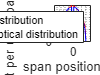



plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')

plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')
plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')

% 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot)

grid on
grid minor
xlabel('span position [m]')
ylabel('Lift per unit span [N/m]')
legend('Current distribution','','aimed elliptical distribution')

hold off

## Discretization of parameters

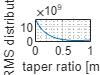

for w = 1:100
    test(w).Sweep = 0;
    test(w).Taper = w*0.01;
    % 4.5*pi/180;

    %% discritize planform to plot
    [test(w).c_y, test(w).span_disc,test(w).quarterchord,test(w).c_bar,test(w).span] = planformcalc(Aircraft.AR, test(w).Sweep, test(w).Taper, Aircraft.Sref, Condition.discret);

    test(w).semispan = test(w).span*0.5;
    test(w).thetadist = acos(test(w).span_disc/test(w).span_disc(end));

    test(w).twist_dis = linspace(0,Wing.twist,length(test(w).span_disc));
    test(w).alpha_0_dis = linspace(Airfoil(1).alpha0,Airfoil(2).alpha0,length(test(w).span_disc));
    test(w).incidence_dis = Wing.incidence*ones(1,length(test(w).span_disc));
    test(w).alpha_dis = test(w).twist_dis - test(w).alpha_0_dis + test(w).incidence_dis;

    test(w).a_dis = linspace(Airfoil(1).a,Airfoil(2).a,length(test(w).span_disc));
    test(w).mu_dis = (test(w).a_dis.*test(w).c_y)/(4.*Aircraft.AR*test(w).c_bar);

    test(w).LHS = zeros(floor(Wing.panelnum/2),1);
    test(w).RHS = zeros(floor(Wing.panelnum/2),floor(Wing.panelnum/2));

    for i = 1:floor(Wing.panelnum/2)
        for j = 1 : floor(Wing.panelnum/2)
            %         tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)));
            [temp,tempind]= min(abs(test(w).thetadist-i*pi/Wing.panelnum));
            test(w).LHS(i,1) = test(w).mu_dis(tempind)*test(w).alpha_dis(tempind)*sin(test(w).thetadist(tempind));
            test(w).RHS(i,j) = sin((2*j-1)*test(w).thetadist(tempind))*((2*j-1)*test(w).mu_dis(tempind) + sin(test(w).thetadist(tempind)));
        end
    end

    clear temp tempind
    test(w).Aseries = test(w).RHS\test(w).LHS;
    test(w).gamma_span_coef = 4*test(w).semispan*Condition.Uinf;
    test(w).gamma_sum = 0;

    for n = 1:floor(Wing.panelnum/2)
        test(w).gamma_sum = test(w).gamma_sum + test(w).Aseries(n)*sin((2*n-1)*test(w).thetadist);
    end

    test(w).gamma_plot = test(w).gamma_span_coef*test(w).gamma_sum;
    test(w).gamma_ellipse = 4*test(w).semispan*Condition.Uinf*test(w).Aseries(1)*sin(test(w).thetadist);
    test(w).Lift_plot = test(w).gamma_plot*Condition.Uinf*rho.cruise;
    test(w).Lift_ellipse_plot = test(w).gamma_ellipse * Condition.Uinf*rho.cruise;

    % Lift_plot(1:find(span_disc == fuselage_rad)) = 0; %for fuselage to 0



%     Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot);
%     Totalliftcheck = 4*rho*Uinf^2*semispan^2*Aseries(1)*pi/2;
%     Cl_plot = Lift_plot./(0.5*rho*Uinf^2.*c_y);
%     Cl_ellipse_plot = Lift_ellipse_plot./(0.5*rho*Uinf^2.*c_y);
    %         CL_des = Totallift/(0.5*rho*Uinf^2*Sref);

    Lift_residual_compare(w) = sum((test(w).Lift_plot - test(w).Lift_ellipse_plot).^2);
end
% [kplot,wplot] = meshgrid(0.01*[1:100],0.5*[1:20])

plot(0.01*[1:100],Lift_residual_compare)
hold on
% plot(0.83,Lift_residual_compare(83),'xk')
grid on
grid minor
xlabel('taper ratio [m]')
ylabel('RMS distribution')

hold off

## Propwake Scaled Cl

Prop.datarawlift = [-1.000864487	0.029393939
-0.979652366	0.071818182
-0.940207845	0.083939394
-0.897723824	0.09
-0.861291213	0.071818182
-0.824876995	0.077878788
-0.788462776	0.083939394
-0.752057755	0.102121212
-0.703513128	0.12030303
-0.661029107	0.126363636
-0.618545087	0.132424242
-0.579114361	0.162727273
-0.536625741	0.162727273
-0.494137122	0.162727273
-0.463765117	0.132424242
-0.430344415	0.083939394
-0.393934796	0.096060606
-0.375752977	0.132424242
-0.360624454	0.193030303
-0.354591438	0.241515152
-0.345532717	0.302121212
-0.339504299	0.356666667
-0.327442866	0.45969697
-0.315372235	0.550606061
-0.306336506	0.641515152
-0.291240171	0.744545455
-0.285262335	0.865757576
-0.273210098	0.980909091
-0.264201959	1.108181818
-0.252186508	1.271818182
-0.249257369	1.411212121
-0.237223525	1.550606061
-0.231250287	1.677878788
-0.219221042	1.823333333
-0.213234009	1.932424242
-0.207242378	2.035454545
-0.19519474	2.156666667
-0.192233412	2.253636364
-0.183174691	2.314242424
-0.17107647	2.368787879
-0.152890054	2.399090909
-0.125516163	2.32030303
-0.116333287	2.217272727
-0.104101715	2.096060606
-0.091856348	1.956666667
-0.079610981	1.817272727
-0.070391318	1.665757576
-0.058136754	1.514242424
-0.045877592	1.356666667
-0.036662528	1.211212121
-0.021396055	1.09
0.005982434	1.005151515
0.039357153	1.017272727
0.072754863	0.999090909
0.106161769	0.968787879
0.133498873	0.938484848
0.169908493	0.950606061
0.206336506	0.938484848
0.236722307	0.89
0.255019083	0.774848485
0.264188164	0.69
0.276405941	0.586969697
0.297733021	0.477878788
0.316011404	0.386969697
0.343394491	0.296060606
0.370768382	0.217272727
0.392058675	0.156666667
0.41941877	0.096060606
0.452811882	0.083939394
0.504409804	0.077878788
0.56207293	0.077878788
0.640984963	0.071818182
0.692582885	0.065757576
0.756320412	0.05969697
0.817018439	0.05969697
0.871651262	0.053636364
0.938414494	0.05969697
0.968768106	0.053636364
0.99610521	0.023333333
];
%propwash vector
Prop.Thrustcoef = 0.78;
Aircraft.Totaldrag = 28705;
Aircraft.Thrustcoef = Aircraft.Totaldrag/(Aircraft.Sref*0.5*rho.cruise*Condition.Uinf^2);
Aircraft.Thrustratio = Aircraft.Thrustcoef/Prop.Thrustcoef;
Aircraft.Proppos = 6;
Prop.Diameter = 4;
Prop.Scaledshifted = [Prop.dataraw(:,1).*Prop.Diameter/0.53 + Aircraft.Proppos, Prop.dataraw(:,2).*Aircraft.Thrustratio];
Prop.coefs = spline(Prop.Scaledshifted(:,1),Prop.Scaledshifted(:,2));

Prop.Cl_superpos = ppval(Prop.coefs,Wing.span_disc);

## Propwake Drag

Prop.datarawdrag = [-1.000864487	0.029393939
-0.979652366	0.071818182
-0.940207845	0.083939394
-0.897723824	0.09
-0.861291213	0.071818182
-0.824876995	0.077878788
-0.788462776	0.083939394
-0.752057755	0.102121212
-0.703513128	0.12030303
-0.661029107	0.126363636
-0.618545087	0.132424242
-0.579114361	0.162727273
-0.536625741	0.162727273
-0.494137122	0.162727273
-0.463765117	0.132424242
-0.430344415	0.083939394
-0.393934796	0.096060606
-0.375752977	0.132424242
-0.360624454	0.193030303
-0.354591438	0.241515152
-0.345532717	0.302121212
-0.339504299	0.356666667
-0.327442866	0.45969697
-0.315372235	0.550606061
-0.306336506	0.641515152
-0.291240171	0.744545455
-0.285262335	0.865757576
-0.273210098	0.980909091
-0.264201959	1.108181818
-0.252186508	1.271818182
-0.249257369	1.411212121
-0.237223525	1.550606061
-0.231250287	1.677878788
-0.219221042	1.823333333
-0.213234009	1.932424242
-0.207242378	2.035454545
-0.19519474	2.156666667
-0.192233412	2.253636364
-0.183174691	2.314242424
-0.17107647	2.368787879
-0.152890054	2.399090909
-0.125516163	2.32030303
-0.116333287	2.217272727
-0.104101715	2.096060606
-0.091856348	1.956666667
-0.079610981	1.817272727
-0.070391318	1.665757576
-0.058136754	1.514242424
-0.045877592	1.356666667
-0.036662528	1.211212121
-0.021396055	1.09
0.005982434	1.005151515
0.039357153	1.017272727
0.072754863	0.999090909
0.106161769	0.968787879
0.133498873	0.938484848
0.169908493	0.950606061
0.206336506	0.938484848
0.236722307	0.89
0.255019083	0.774848485
0.264188164	0.69
0.276405941	0.586969697
0.297733021	0.477878788
0.316011404	0.386969697
0.343394491	0.296060606
0.370768382	0.217272727
0.392058675	0.156666667
0.41941877	0.096060606
0.452811882	0.083939394
0.504409804	0.077878788
0.56207293	0.077878788
0.640984963	0.071818182
0.692582885	0.065757576
0.756320412	0.05969697
0.817018439	0.05969697
0.871651262	0.053636364
0.938414494	0.05969697
0.968768106	0.053636364
0.99610521	0.023333333
];
Prop.Thrustcoef = 0.78;
Aircraft.Totaldrag = 28705;
Aircraft.Thrustcoef = Aircraft.Totaldrag/(Aircraft.Sref*0.5*rho.cruise*Condition.Uinf^2);
Aircraft.Thrustratio = Aircraft.Thrustcoef/Prop.Thrustcoef;
Aircraft.Proppos = 6;
Prop.Diameter = 4;
Prop.Scaledshifted = [Prop.dataraw(:,1).*Prop.Diameter/0.53 + Aircraft.Proppos, Prop.dataraw(:,2).*Aircraft.Thrustratio];
Prop.coefs = spline(Prop.Scaledshifted(:,1),Prop.Scaledshifted(:,2));

Prop.Cl_superpos = ppval(Prop.coefs,Wing.span_disc);

## Function for plotting Prep

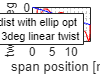

for i = 1:10
    [Wing.Lift_plot,Wing.Lift_ellipse_plot,Wing.DragI_plot,Aircraft.Totallift,Aircraft.Totalliftcheck_nofuselage,Wing.Cl_plot,Wing.Cl_ellipse_plot,Wing.CDi_plot, Wing.CL_des,Wing.CD_des_ind] = Plotting(Angle.twist_dis, Angle.alpha_0_dis, Angle.incidence_dis, Wing.thetadist, Wing.panelnum, Wing.mu_dis,Wing.semispan,Condition.Uinf,rho.cruise,Wing.c_y,Aircraft.Sref,Condition.Cruise_Mach,Aircraft.AR,Condition.MTOW,Aircraft.fuselage_rad,Wing.span_disc);
    Wing.Twist_added = (Wing.Cl_ellipse_plot - Wing.Cl_plot)./Wing.a_dis;
    Angle.twist_dis = Angle.twist_dis + Wing.Twist_added;
end

plot(Wing.span_disc,Angle.twist_dis*180/pi ,'r')
hold on
plot(Wing.span_disc,Angle.defaulttwist*180/pi ,'b')
hold off
% + Angle.incidence_dis*180/pi
grid on
grid minor
xlabel('span position [m]')
ylabel('twist [degs]')
legend('twist dist with ellip opt','Initial 3deg linear twist')


plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')

plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')
plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')

disp('Cdinduced=')

Cdinduced=


disp(Wing.CD_des_ind)

    0.0141



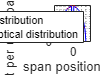


% 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot)
hold off
grid on
grid minor
xlabel('span position [m]')
ylabel('Lift per unit span [N/m]')
legend('Current distribution','','aimed elliptical distribution')

## Adding Propeller effects

Wing.Cl_plot = Wing.Cl_plot + Prop.Cl_superpos;
Wing.Lift_plot = 0.5*rho.cruise*Condition.Uinf^2.*Wing.c_y.*Wing.Cl_plot;

plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')

plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')
plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')
disp('Cdinduced=')

Cdinduced=


disp(Wing.CD_des_ind)

    0.0141



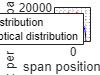

% 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot)
hold off
grid on
grid minor
xlabel('span position [m]')
ylabel('Lift per unit span [N/m]')
legend('Current distribution','','aimed elliptical distribution')

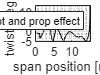


for i = 1:10
    Wing.Cl_plot = Wing.Cl_plot + Prop.Cl_superpos;
    Wing.Lift_plot = 0.5*rho.cruise*Condition.Uinf^2.*Wing.c_y.*Wing.Cl_plot;
    Wing.Twist_added = (Wing.Cl_ellipse_plot - Wing.Cl_plot)./Wing.a_dis;
    Angle.twist_dis = Angle.twist_dis + Wing.Twist_added;
    [Wing.Lift_plot,Wing.Lift_ellipse_plot,Wing.DragI_plot,Aircraft.Totallift,Aircraft.Totalliftcheck_nofuselage,Wing.Cl_plot,Wing.Cl_ellipse_plot,Wing.CDi_plot, Wing.CL_des,Wing.CD_des_ind] = Plotting(Angle.twist_dis, Angle.alpha_0_dis, Angle.incidence_dis, Wing.thetadist, Wing.panelnum, Wing.mu_dis,Wing.semispan,Condition.Uinf,rho.cruise,Wing.c_y,Aircraft.Sref,Condition.Cruise_Mach,Aircraft.AR,Condition.MTOW,Aircraft.fuselage_rad,Wing.span_disc);
end

Wing.Cl_plot = Wing.Cl_plot + Prop.Cl_superpos;
Wing.Lift_plot = 0.5*rho.cruise*Condition.Uinf^2.*Wing.c_y.*Wing.Cl_plot;
Aircraft.Totallift = 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot);
plot(Wing.span_disc,Angle.twist_dis*180/pi ,'k');
% + Angle.incidence_dis*180/pi
grid on
grid minor
xlabel('span position [m]')
ylabel('twist [degs]')
legend('twist dist with ellip opt and prop effect')

## plotting the lift dist and cl dist

plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')

plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')
plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')

% 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot)
disp('Cdinduced=')
disp(Wing.CD_des_ind)
grid on
grid minor
xlabel('span position [m]')
ylabel('Lift per unit span [N/m]')
legend('Current distribution','','aimed elliptical distribution')

hold off

plot(1*cos(Wing.thetadist),Wing.Cl_plot,'r')
hold on
plot(-1*cos(Wing.thetadist),Wing.Cl_plot,'r')

plot(-1*cos(Wing.thetadist),Wing.Cl_ellipse_plot,'b')
plot(1*cos(Wing.thetadist),Wing.Cl_ellipse_plot,'b')
grid on
grid minor

% ylim([0 0.7])
hold off
xlabel('% span position')
ylabel('Sectional Cl')
legend('Current distribution','','aimed elliptical distribution')

plot(1*cos(Wing.thetadist),Wing.CDi_plot,'r')
hold on
plot(-1*cos(Wing.thetadist),Wing.CDi_plot,'r')

grid on
grid minor

% ylim([0 0.7])
hold off
xlabel('% span position')
ylabel('Sectional CDi')
legend('Current distribution','')



## Function for planform

function [c_y,span_disc,quarterchord,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret) 
%(AR, Sweep, Taper, c_bar) 
span = sqrt(AR * Sref);
c_bar = Sref/span;
span_disc = [0:discret:span/2];
syms croot;
eqn = (croot+Taper*croot)*(span/2) == Sref;
croot = double(solve(eqn,croot));
c_y =  (Taper-1)*croot/(span/2).*span_disc + croot;
quarterchord =  span_disc .* tand(Sweep);


% s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
% Sref_1 = (1 + Taper) * s_1;
% span_disc_1 = [0:0.01:s_1];
% c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
% c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
% ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
% s = ratio*s_1;
% Sref = ratio * (1 + Taper) * s;
% span_disc = [0:0.01:s];
% c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
% temp1 = (c_y - c_bar).^2;
% MACpos = find(temp1 == min(temp1));
% quarterchord =  span_disc .* tand(Sweep);
end

## Function for CL_3D

function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end

## Function for plotting

function [Lift_plot,Lift_ellipse_plot,DragI_plot,Totallift,Totalliftcheck,Cl_plot,Cl_ellipse_plot,CDi_plot,CL_des,CD_des_ind] = Plotting(twist_dist, alpha_0_dis, incidence_dis, thetadist, panelnum,mu_dis,semispan,Uinf,rho,c_y,Sref,Cruise_Mach,AR,MTOW,fuselagerad,span_disc)

alpha_opt = twist_dist - alpha_0_dis + incidence_dis;

LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));
for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_opt(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end

Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;
downwash_sum = 0;
for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin((2*n-1)*thetadist);
    downwash_sum = downwash_sum + (2*n-1) * Aseries(n) * (sin((2*n-1)*thetadist)/sin(thetadist));
end

gamma_plot = gamma_span_coef*gamma_sum;
downwash_plot = -Uinf*downwash_sum;
DragI_plot = rho.*downwash_plot.*gamma_plot;

tempa = thetadist(find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):end);
tempb = sin(thetadist(find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):end)).^2;
% plot(tempa,tempb)
fuseliftloss = -2*trapz(tempa,tempb);
A_ref = MTOW/(4*rho*Uinf^2*semispan^2*(fuseliftloss));



gamma_ellipse = 4*semispan*Uinf*A_ref*sin(thetadist);



tempc = [1:find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad)))];
Lift_plot = gamma_plot*Uinf*rho;
Lift_ellipse_plot = gamma_ellipse * Uinf*rho;
Lift_plot(tempc) = 0;
Lift_ellipse_plot(tempc) = 0;

Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot);
Totalliftcheck = 4*rho*Uinf^2*semispan^2*A_ref*pi/2;
Cl_plot = Lift_plot./(0.5*rho*Uinf^2.*c_y);
Cl_ellipse_plot = Lift_ellipse_plot./(0.5*rho*Uinf^2.*c_y);
CDi_plot = -DragI_plot./(0.5*rho*Uinf^2.*c_y);
CL_des = Totallift/(0.5*rho*Uinf^2*Sref)/ sqrt(1-Cruise_Mach^2);
CL_des_comp = pi*AR*Aseries(1) * sqrt(1-Cruise_Mach^2);

CD_des_ind = (pi*AR) * sum(Aseries.*[1:1:size(Aseries,1)]'.*Aseries) * sqrt(1-Cruise_Mach^2);


end